# WP3

Nota: prima di eseguire il codice assicurarsi di aver impostato come working directory di MATLAB la cartella "WP1".

## Parametri del modello

clear all  clc;
p1 = 0.0151; %tasso base di rimozione del glucosio dal sangue
p2 = 0.0313; %tasso rimozione del glucosio dovuto all'insulina
p3 = 0.0097;
ge = 0.97;
ie = 0.003;
u_eq=1.003;

I parametri nella sezione successiva sono il risultato dei work package precedenti.

x_eq = [0.0451; 0.3099];
x1_eq = x_eq(1);
x2_eq = x_eq(2);
% Il K è il risultato del WP2
K = [-1272.43538878761    165.594962781475    408.248290463863];
A = [-p1-x_eq(2) -x_eq(1); 0 -p2];
B = [0; p3];
C = [1 0];
D = [0];

## Osservatore

Il primo passo nella progettazione dell'osservatore è trovare la matrice di osservabilità e controllare se il sistema è osservabile.

W0 = [C;C*A];
rank(W0)

ans = 2

Il sistema ha rango pieno, dunque è osservabile.

A questo punto si procede con il calcolo di L.

% matrice di osservabilità in forma canonica
syms x
polyA = charpoly(A, x);
polyA = coeffs(polyA);
a1 = polyA(2);
a2 = polyA(1);
W0_tilde = inv([1,0;a1,1]); %in alternativa W0_tilde = [1 0;-a1 1];

% calcolo dei coefficienti del polinomio desiderato
Sett_time = 2.2;
zeta = 1;
w0 = 5.8/Sett_time;
pd1 = 2*zeta*w0;
pd2 = w0^2;

L = inv(W0)*W0_tilde*[pd1-a1;pd2-a2];
L = eval(L);

Simulazione del sistema LQI con l'osservatore:

simout = sim('v1_lqi_observer.slx');

Valutazione delle performance dinamiche:

t = simout.t;
t = t.Time;
y = simout.y;
u = simout.u;
x = simout.x;
x_hat = simout.x_hat.Data;

x_hat_1_stepinfo = stepinfo(x_hat(:,1),t,x1_eq)

x_hat_1_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 14.2636
     SettlingTime: 14.8272
      SettlingMin: 0.0451
      SettlingMax: 0.0977
        Overshoot: 116.5747
       Undershoot: 0
             Peak: 0.0977
         PeakTime: 0.4754


x_hat_2_stepinfo = stepinfo(x_hat(:,2),t,x2_eq) % Tempo di assestamento 6.3369. Overshoot: 394.6826

x_hat_2_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 7.4072
     SettlingTime: 10.2339
      SettlingMin: -0.6156
      SettlingMax: 0.6547
        Overshoot: 111.2555
       Undershoot: 198.6582
             Peak: 0.6547
         PeakTime: 1.3060


y_stepinfo = stepinfo(y,t,y(end)) % Tempo di assestamento di 12.97min e overshoot del 46%

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 13.3754
     SettlingTime: 14.0567
      SettlingMin: 0.0453
      SettlingMax: 0.1017
        Overshoot: 124.4396
       Undershoot: 0
             Peak: 0.1017
         PeakTime: 0.1796


u_stepinfo = stepinfo(u,t,u(end)) % Picco di 189

u_stepinfo = struct with fields:
         RiseTime: 5.2419e-04
    TransientTime: 3.0014
     SettlingTime: 15.8094
      SettlingMin: -61.4506
      SettlingMax: 175.7395
        Overshoot: 1.7350e+04
       Undershoot: 6.1017e+03
             Peak: 175.7395
         PeakTime: 0.3135


u_min = min(u) % picco minimo

u_min = -61.4506

#### Plot dei grafici

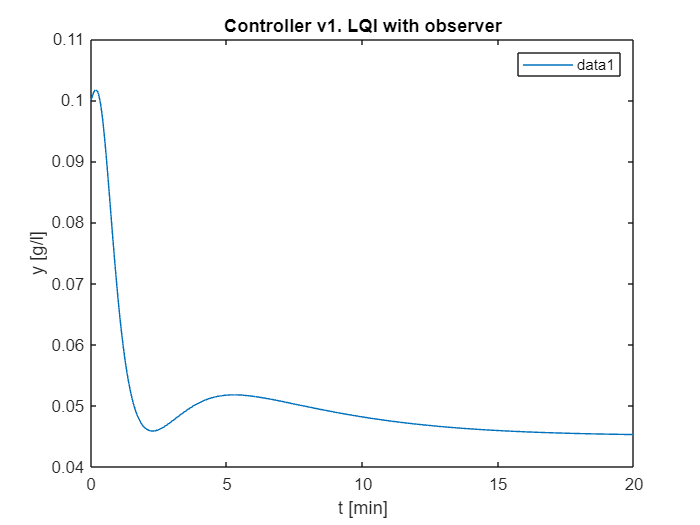

figure
plot(t,y)
legend()
title("Controller v1. LQI with observer")

xlabel("t [min]")
ylabel("y [g/l]")

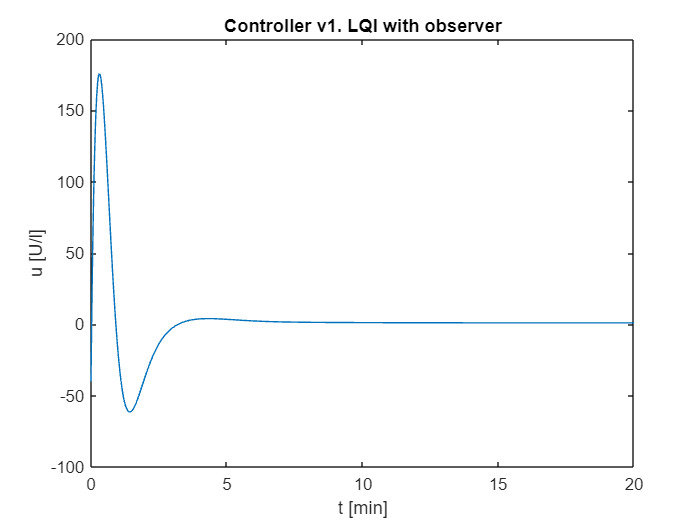

figure
plot(t,u)
title("Controller v1. LQI with observer")
xlabel("t [min]")
ylabel("u [U/l]")

x_tilde = x - x_hat

x_tilde =     0.0549   -0.3099
    0.0549   -0.3099
    0.0549   -0.3099
    0.0549   -0.3097
    0.0549   -0.3087
    0.0547   -0.3039
    0.0542   -0.2888
    0.0538   -0.2739
    0.0533   -0.2577
    0.0527   -0.2405


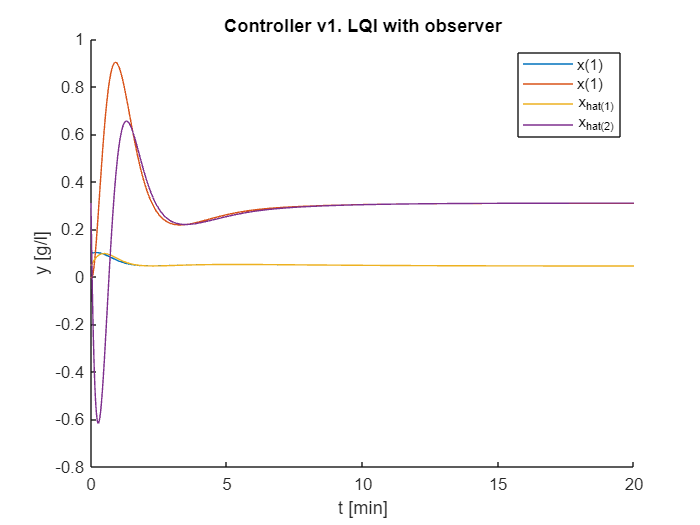

%stepinfo(x_tilde(:,1),t,0)
%stepinfo(x_tilde(:,2),t,0)

figure
hold on
plot(t,x(:,1))
plot(t,x_hat(:,1))
legend("x_1","x2","x_hat(1)","x_hat(2)")
title("Controller v1. LQI with observer")
xlabel("t [min]")
ylabel("y [g/l]")
figure
hold on
plot(t,x(:,2))
plot(t,x_hat(:,2))

legend("x_1","x2","x_hat(1)","x_hat(2)")
title("Controller v1. LQI with observer")

xlabel("t [min]")
ylabel("y [g/l]")



% Sett_time = 1;
% w0 = 5.8/Sett_time;
% zeta =1;
% y_stepinfo = 
%          RiseTime: 1.4121
%     TransientTime: 12.7872
%      SettlingTime: 12.7272
%       SettlingMin: 0.0449
%       SettlingMax: 0.0659
%         Overshoot: 46.1649
%        Undershoot: 0
%              Peak: 0.0659
%          PeakTime: 3.1894
% 
% 
% u_stepinfo = 
%          RiseTime: 0.0088
%     TransientTime: 4.1841
%      SettlingTime: 11.4610
%       SettlingMin: 0.9383
%       SettlingMax: 47.8568
%         Overshoot: 4.7213e+03
%        Undershoot: 1.9093e+04
%              Peak: 189.5179
%          PeakTime: 0.1651

% Sett_time = 1.5;
% y_stepinfo = 
%          RiseTime: 1.4813
%     TransientTime: 13.0552
%      SettlingTime: 12.9933
%       SettlingMin: 0.0413
%       SettlingMax: 0.0683
%         Overshoot: 51.3979
%        Undershoot: 0
%              Peak: 0.0683
%          PeakTime: 3.2388
% 
% 
% u_stepinfo = 
%          RiseTime: 0.0107
%     TransientTime: 4.5370
%      SettlingTime: 11.5940
%       SettlingMin: 0.7800
%       SettlingMax: 42.4907
%         Overshoot: 4.1842e+03
%        Undershoot: 1.1805e+04
%              Peak: 117.0774
%          PeakTime: 0.2722

% Sett_time = 2;
% y_stepinfo = 
%          RiseTime: 1.5523
%     TransientTime: 13.3080
%      SettlingTime: 13.2433
%       SettlingMin: 0.0413
%       SettlingMax: 0.0706
%         Overshoot: 56.6516
%        Undershoot: 0
%              Peak: 0.0706
%          PeakTime: 3.6155
% 
% 
% u_stepinfo = 
%          RiseTime: 0.0114
%     TransientTime: 4.8165
%      SettlingTime: 11.6587
%       SettlingMin: 0.2865
%       SettlingMax: 37.5991
%         Overshoot: 3.6940e+03
%        Undershoot: 8.5971e+03
%              Peak: 85.1991
%          PeakTime: 0.2303

% è possibile controllare che i coefficienti del polinomio caratteristico dell'osservatore siano
% quelli desiderati
syms x
polyObs = charpoly(A-L*C,x);
coeffs_obs = eval(coeffs(polyObs))

coeffs_obs =     6.9504    5.2727    1.0000




%% soluzione con il comando place
% syms x
% polyA = charpoly(A-L*C,x)
% polyA = coeffs(polyA)
% 
% syms s;
% f = s^2+pd1*s+pd2 == 0
% res = solve(f,[s])
% pole1 = eval(res(1));
% pole2 = eval(res(2));
% L_check = place(A.', C.',[pole1 pole2]);
% L_check = L_check.'



%TODO:
%- piazzare meglio i poli dell'osservatore
%- valutare tempo di salita, sovraelongazione ecc della risposta come fatto
% per WP precedenti


